# Cell Tracking Example

This example recreates the cell tracking example you saw in the video lesson. Use this script as a template to apply tracking to other video files. Try changing some of the key parameters and see how the results change. 

## Setup

Initialize empty tables for the tracks. In this example, we also use an analysis function to store information about confirmed tracks (see below), so an empty table for analysis results is also created. 

Running this script will create a video file in your Current Folder. If you want to compare the tracking results with different parameters, be sure to change the output filename.

tracks = table();   
analysisResults = table();

Create `VideoReader` and `VideoWriter` objects and get the number of frames.

videoIn = VideoReader("CellVideo.avi");
outputFileName = "CellTrackingResults.avi";
videoOut = VideoWriter(outputFileName); 
% Ensure the frame rates match
videoOut.FrameRate = videoIn.FrameRate;
numFrames = videoIn.NumFrames; 

## Main Tracking Loop 

The tracking loop below contains the core steps: detection, prediction, assignment, and updating. It also includes analysis and visualization steps. The analysis function adds confirmed tracks to an output table along with the frame number the track was confirmed. After running the code, look at the `analysisResults` table. The height of the table represents the number of confirmed tracks in the video. 

open(videoOut); 

for frameIdx = 1:numFrames

    frame = read(videoIn,frameIdx); 
    
    detections = detectCells(frame); 

    tracks = predictTracks(tracks);

    [tracks,detections] = assignTracksDetections(detections,tracks);
    
    tracks = updateTracks(tracks,detections);
    
    analysisResults = analyzeConfirmedTracks(tracks,analysisResults,frameIdx);

    writeCellTrackingResults(frame,tracks,videoOut);  

end
close(videoOut)

% This resets the persistent variable
clear functions


View the `analysisResults `table and the output video

analysisResults


analysisResults =

  0×0 empty table



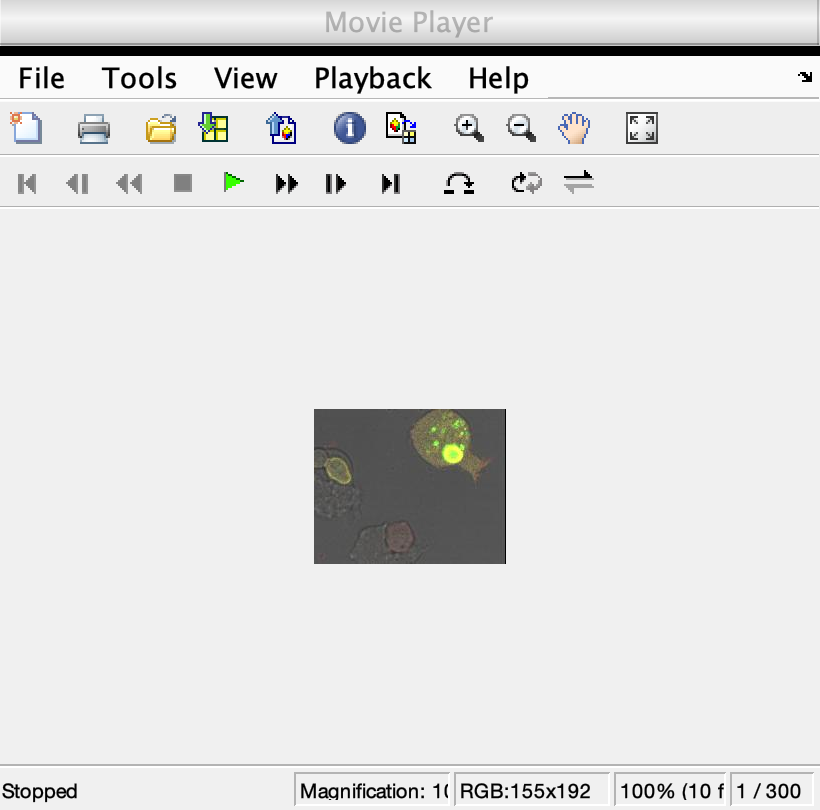

implay(outputFileName)

## Tracking Functions

Below are the functions used in the main loop above.

### Predicting Tracks

Use `predict` function to predict a new location for all tracks. You don't need to make modifications to the `predictTracks` function for this example. 

function tracks = predictTracks(tracks)
    for idx = 1:height(tracks)
        tracks.PredictedLocation(idx,:) = predict(tracks.KalmanFilter{idx});
    end
end


### Assign Detections to Tracks 

This function creates the cost matrix and assigns detections to tracks. A key variable in the assignment function is the `costOfNonAssignment`. 

function [tracks,detections] = assignTracksDetections(detections,tracks)

    % Compute the cost of assigning each detection to each track.
    cost = zeros(height(tracks),height(detections));
    for idx = 1:height(tracks)
        cost(idx,:) = distance(tracks.KalmanFilter{idx},detections.centroids);
    end
    
    % Solve the assignment problem using shipped MATLAB function 
    costOfNonAssignment = 5; 
    assignedIdxPairs = assignDetectionsToTracks(cost,costOfNonAssignment);
    
    % Set detected flag and add detected location to detected tracks
    if ~isempty(tracks)
        tracks.Visible(:) = false; 
        tracks.Visible(assignedIdxPairs(:,1)) = true; 
        tracks.DetectedLocation(assignedIdxPairs(:,1),:) = detections.centroids(assignedIdxPairs(:,2),:); 
    end
    
    % Set assignment flag to detections 
    if ~isempty(detections)
        detections.assigned(:) = false; 
        detections.assigned(assignedIdxPairs(:,2)) = true; 
    end

end

### Updating Tracks 

This function updates existing tracks and creates new tracks for unassigned detections. There are many important parameters here that can affect your tracking results. Refer back to the reference reading for details. 

This is also where you initialize your Kalman filter and add any meta-data to tracks that you need for analysis. 

function tracks = updateTracks(tracks,detections)

    % Initialize persistent counter 
    persistent TrackId;
    if isempty(TrackId)
        TrackId = 1; 
    end


    % Update tracked locations and states using available detections 
    for idx = 1:height(tracks)
        if tracks.Visible(idx)
           tracks.TrackedLocation(idx,:) = correct(tracks.KalmanFilter{idx},tracks.DetectedLocation(idx,:));
        end
    end

    % Update remaining track variables 
    if ~isempty(tracks)
        % Set tracked location equal to prediction for undetected tracks  
        tracks.TrackedLocation(~tracks.Visible,:) = tracks.PredictedLocation(~tracks.Visible,:); 
    
        % Increment all track ages 
        tracks.Age = tracks.Age + 1;

        % Increment all visible tracks total visible count 
        tracks.TotalVisibleCount(tracks.Visible) = tracks.TotalVisibleCount(tracks.Visible) + 1; 

        % Confirm tracks detected enough 
        trackConfirmationThreshold = 3; 
        tracks.Confirmed = tracks.TotalVisibleCount > trackConfirmationThreshold;
        
        % Reset the counter for consecutive frames undetected if detected
        tracks.ConsecutiveInvisibleCount(tracks.Visible) = 0;

        % Increment the counter for consecutive frames undetected 
        tracks.ConsecutiveInvisibleCount(~tracks.Visible) = tracks.ConsecutiveInvisibleCount(~tracks.Visible) + 1;

        % Compute the fraction of each track's age for which it was visible
        visibility = tracks.TotalVisibleCount ./ tracks.Age;
        
        % Set thresholds for age and visibility and considered missing
        ageThreshold = 10;
        visibilityThreshold = 0.6;
        lostThreshold = 10;

        % Find the indices of tracks to delete 
        newInds = tracks.Age <= ageThreshold; 
        lowVisibilityInds = visibility < visibilityThreshold; 
        lostInds = tracks.ConsecutiveInvisibleCount >= lostThreshold;

        deleteInds = ( newInds & lowVisibilityInds ) | lostInds ; 
        
        % Delete tracks
        tracks = tracks(~deleteInds,:); 
    end
    
    % Create new tracks for unassigned detections 
    for idx = 1:height(detections)

        if ~detections.assigned(idx)
            
            % Set Kalman Filter parameters 
            InitialLocation = detections.centroids(idx,:);
            FilterType = "ConstantVelocity"; 
            InitialEstimateError = [200, 50]; 
            MotionNoise = [100, 25]; 
            MeasurementNoise = 100;

            % Create a Kalman filter object.
            KalmanFilter = configureKalmanFilter(FilterType,InitialLocation, ...
                InitialEstimateError, MotionNoise, MeasurementNoise);
            
            % Set initial variables for new track
            DetectedLocation = InitialLocation; 
            TrackedLocation = InitialLocation; 
            PredictedLocation = InitialLocation; 
            PredictedState = zeros(1,4);
            Age = 1;
            TotalVisibleCount = 1; 
            ConsecutiveInvisibleCount = 0;
            Visible = true; 
            Confirmed = false; 

            % Convert Kalman filter to a cell for stacking 
            KalmanFilter = {KalmanFilter}; 

            % Create new track row
            newTrack = table(TrackId,DetectedLocation,TrackedLocation, ...
                PredictedLocation,PredictedState,...
                KalmanFilter,Age,TotalVisibleCount,...
                ConsecutiveInvisibleCount,Visible,Confirmed);
            
            % Add it to the array of tracks.
            tracks = [tracks; newTrack]; 
    
            TrackId = TrackId + 1;
        end

    end

end

## Analysis and Visualization Functions 

### Tracks Analysis 

You can add functions to your main loop to analyze your tracks. Remember that you can add any metadata to your tracks that you have access to. The function below creates a table of confirmed tracks and adds the frame number that the track was confirmed.

It works by looping through all the current tracks. 

- If a track is confirmed but not in the results table (because the results table is still empty or it's a newly confirmed track), then it is added to the output results table.

- If the track is confirmed and already in the results table, then this function does not do anything.

function results = analyzeConfirmedTracks(tracks,results,frameNumber)

    for idx = 1:height(tracks)
        % Only add confirmed tracks to the results table
        % tracks.Confirmed is a logical variable.
        if  tracks.Confirmed(idx)
            
            % If results table is empty, add a new row to the table
            if isempty(results) 

                % Initialize a new row for the results 
                ConfirmedTrackId = tracks.TrackId(idx);
                ConfirmedFrame = frameNumber;
                newRow = table(ConfirmedTrackId,ConfirmedFrame); 

                % Add the new row to the results table  
                results = [results; newRow]; 

            % If tracks exist, check if the current track is already
            % confirmed and in the tracks table. If not, add it.
            elseif ~ismember(tracks.TrackId(idx),results.ConfirmedTrackId)

                ConfirmedTrackId = tracks.TrackId(idx);
                ConfirmedFrame = frameNumber;
                newRow = table(ConfirmedTrackId,ConfirmedFrame); 

                % Add the new row to the results table  
                results = [results; newRow];

            end

        end
    end
 
end

### Output Video Writing 

Add the track location and a label to the current frame if a track is present. Then write the frame to the output video.

function writeCellTrackingResults(frame,tracks,videoOut)
    
    if ~isempty(tracks)
        % Extract the confirmed tracks
        displayTracks = tracks(tracks.Confirmed,:); 
    
        if ~isempty(displayTracks) 
        % Add labels to tracks and display them near locations 
        labels = "Yeast " + displayTracks.TrackId; 
        frame = insertText(frame, ...
            displayTracks.TrackedLocation - 30,labels,"FontSize",9);
        frame = insertMarker(frame, ...
            displayTracks.TrackedLocation,"+","color","black");
        end
    end
   
    writeVideo(videoOut,frame); 

end

*Copyright 2022 The MathWorks, Inc.*